clear;
% Author: Gustav Kjellberg


# Lab 2 - Feature extraction

#### First, let's read the data from the three different tracks.

[Y1, FS1] = audioread('Songs/melody_1.wav');
[Y2, FS2] = audioread('Songs/melody_2.wav');
[Y3, FS3] = audioread('Songs/melody_3.wav');


#### Then, set the length of the window, 0.03 is default.


lengthOfWindow = 0.03


lengthOfWindow = 0.0300

#### Use the data yielded from audioread and extract the 3 features

- Pitch: frIseq(1,:) 80 - 1100 Hz

- Correlation coefficient ($$\rho$$): frIseq(2,:) 

- Esitmates of per-sample intensity: frIseq(3,:)

frIseqT1 = GetMusicFeatures(Y1,FS1,lengthOfWindow);
frIseqT2 = GetMusicFeatures(Y2,FS2,lengthOfWindow);
frIseqT3 = GetMusicFeatures(Y3,FS3,lengthOfWindow);


#### Plot the frequencies for the three different signals. Note that two melodies are from the same song and should thus be similair.

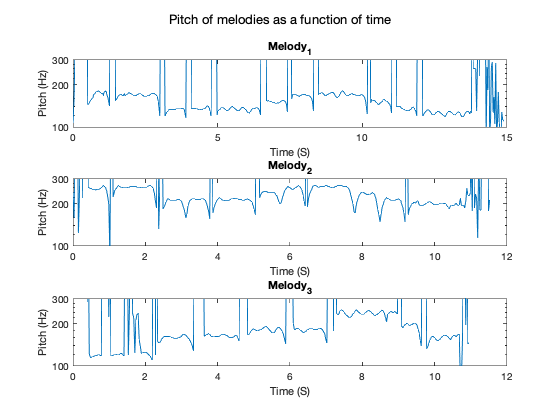


figure;
sgtitle('Pitch of melodies as a function of time');
fig1 = subplot(3,1,1);
t_1 = 0.00:lengthOfWindow:(length(frIseqT1(1,:))-1)*0.03;
plot(t_1, frIseqT1(1,:));
xlabel('Time (S)');
ylabel('Pitch (Hz)');
title('Melody_1')

fig2 = subplot(3,1,2);
t_2 = 0.00:lengthOfWindow:(length(frIseqT2(1,:))-1)*0.03;
plot(t_2, frIseqT2(1,:));
xlabel('Time (S)');
ylabel('Pitch (Hz)');
title('Melody_2')

fig3 = subplot(3,1,3);
t_3 = 0.00:lengthOfWindow:(length(frIseqT3(1,:))-1)*0.03;
plot(t_3, frIseqT3(1,:));
xlabel('Time (S)');
ylabel('Pitch (Hz)');
title('Melody_3')
set([fig1 fig2 fig3], 'YScale','log');

set([fig1 fig2 fig3], 'YLim', [100 300]);

#### Let's now plot the per-sample intensity, note that the time is still the same as the above figure.

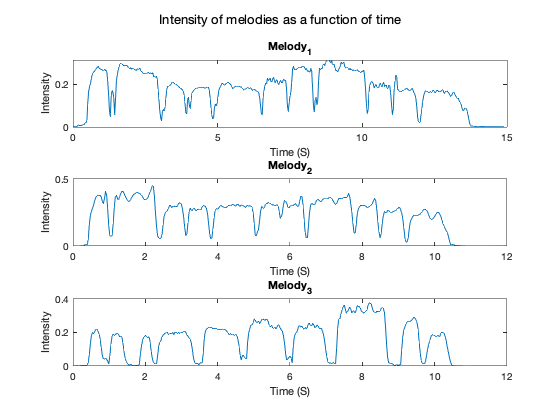


figure;
sgtitle('Intensity of melodies as a function of time');
subplot(3,1,1);
plot(t_1, frIseqT1(3,:));
xlabel('Time (S)');
ylabel('Intensity');
title('Melody_1')

subplot(3,1,2);
plot(t_2, frIseqT2(3,:));
xlabel('Time (S)');
ylabel('Intensity');
title('Melody_2')

subplot(3,1,3);
plot(t_3, frIseqT3(3,:));
xlabel('Time (S)');
ylabel('Intensity');

title('Melody_3')


#### Finally let's have look at the correlation, note that the time is still the same as the above figure. (Closer to one is better). This should tell who is the better singer.

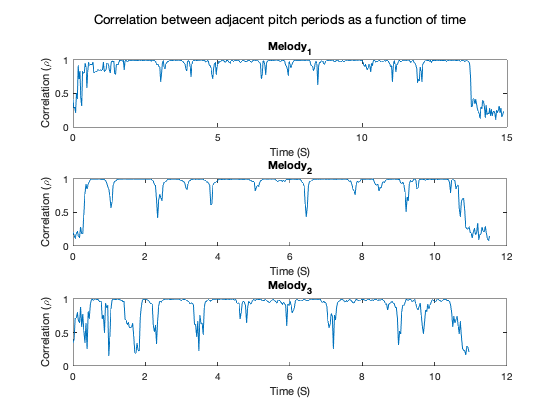


figure;
sgtitle('Correlation between adjacent pitch periods as a function of time');
subplot(3,1,1);
plot(t_1, frIseqT1(2,:));
xlabel('Time (S)');
ylabel('Correlation (\rho)');
title('Melody_1')

subplot(3,1,2);
plot(t_2, frIseqT2(2,:));
xlabel('Time (S)');
ylabel('Correlation (\rho)');
title('Melody_2')

subplot(3,1,3);
plot(t_3, frIseqT3(2,:));
xlabel('Time (S)');
ylabel('Correlation (\rho)');

title('Melody_3')

## Let's now use the postprocessing created in order to see if we can extraxt features that fit the hmm.

% ---- Uncomment the lines below if you want to verify that it works for
% ---- modifying the pitches.

%frIseqT1 = frIseqT1*3;
%frIseqT2 = frIseqT2*3;
%frIseqT3 = frIseqT3*3;
features_song_1 = Postprocess(frIseqT1);
features_song_2 = Postprocess(frIseqT2);
features_song_3 = Postprocess(frIseqT3);
features_song_1_org = features_song_1;
features_song_2_org = features_song_2;
features_song_3_org = features_song_3;

[https://se.mathworks.com/help/signal/ref/dtw.html](https://se.mathworks.com/help/signal/ref/dtw.html)

[d1, i11, i21] = dtw(features_song_1, features_song_2);
[d2, i12, i22] = dtw(features_song_2, features_song_3);
[d3, i13, i23] = dtw(features_song_1, features_song_3);


We see above that the lowest value is actually yielded for melody 1 and 2, that being those that are from the same song. Further, we could try to plot the wrapped signals.

a1w = features_song_1(i11);
a2w = features_song_2(i21);

t = (0:lengthOfWindow:(numel(i11)-1)*lengthOfWindow);


duration = 16.0800

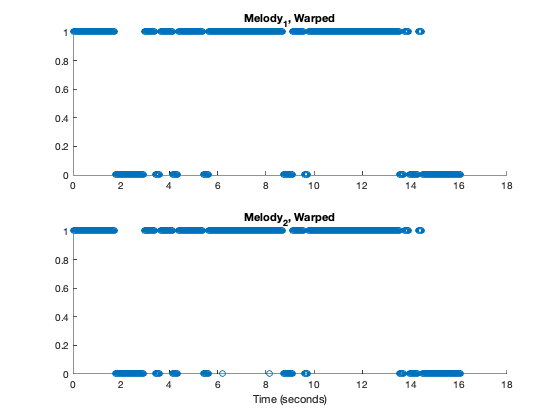

duration = t(end)
figure;
subplot(2,1,1)
scatter(t,a1w)
title('Melody_1, Warped')
subplot(2,1,2)
scatter(t,a2w)
title('Melody_2, Warped')

xlabel('Time (seconds)')

a1w = features_song_1(i12);
a2w = features_song_3(i22);

t = (0:lengthOfWindow:(numel(i12)-1)*lengthOfWindow);


duration = 13.8000

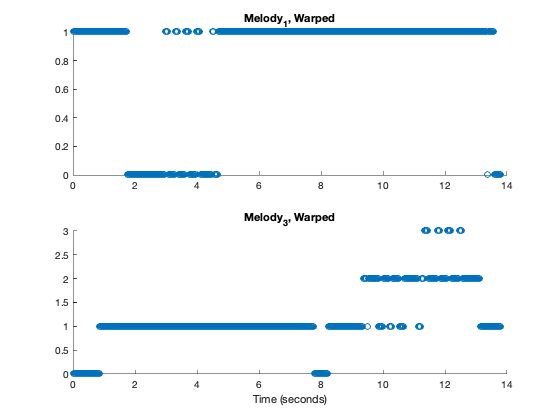

duration = t(end)
subplot(2,1,1)
scatter(t,a1w)
title('Melody_1, Warped')
subplot(2,1,2)
scatter(t,a2w)
title('Melody_3, Warped')

xlabel('Time (seconds)')

a1w = features_song_1(i13);
a2w = features_song_3(i23);

t = (0:lengthOfWindow:(numel(i13)-1)*lengthOfWindow);


duration = 10.8000

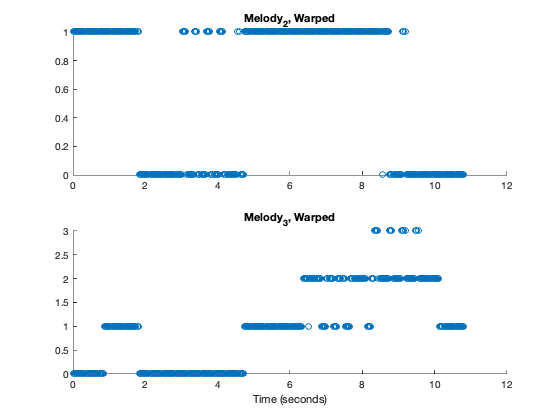

duration = t(end)
subplot(2,1,1)
scatter(t,a1w)
title('Melody_2, Warped')
subplot(2,1,2)
scatter(t,a2w)
title('Melody_3, Warped')

xlabel('Time (seconds)')

---------x = 1.0 ---------


**Finally, let's look at the distance between the signals that the dynamic time warping yielded.**

disp('---------x = 1.0 ---------')

Distance_Melody1_and_2 = 2

Distance_Melody1_and_2 = d1

Distance_Melody1_and_3 = 182

Distance_Melody1_and_3 = d2

Distance_Melody2_and_3 = 234

Distance_Melody2_and_3 = d3

As we can clearly see, the distance between the signals of the first and second melody in lower than that of melody 1 and 3 and significantly lower than that of melody 2 and 3. Further, by visual inspection of the graphs above, it is clear that melody 1 & 2 are more similair in shape than the others.

### Conclusion

By taking the logarithmic value of the frequency and intensity but leaving the relation values alone, we can calculate the mean and variance of the three features. By visualizing the data as a normal-distribution, we assume that we can use the mean and variance to identify noise and silent segments. This is done by marking values of frequency that falls outside of the interval$$[ \overline{frequency}-std(frequency),\overline{frequency}+std(frequency)]$$ as noise, since these don't match the more common values and are thus regerded as outliers. Further, we mark the relationship values that falls below the mean as outliers (noise) and the same for intensity. As a stronger relation is better, we want to keep those values. As mentioned in the assignment, the model should not be sensitive to increased loadness (intensity), therefore we chose not to set an upper bound for outliers there.

There are a few properties defined in the assignment that the feature extractor must have

- The possibility to distinguish between diffrent melodier. - This is fulfilled as shown by warped melodies above.

- Should allow to distinguish between note sequences with the same pitch track, but where note or pause durations differ. - This can be seen in how the time warped plots if melody_1 and melody_2 is very similair. 

- The features are created by utalizing the [Twelfth root of two](https://en.wikipedia.org/wiki/Twelfth_root_of_two), which looks at the quotient between the base frequency (f_0) and any other frequency at time t (f_t) $12*log_2(\frac{f_t}{f_0})$ so any scalar transformation wont have effect.

- Noises are filtered out with a hueristic that identifies outliers in the data and sets all those datapoints to 0, as the chosen feature output is discrete to out HMM.

### Robustness

To verify that the model (3) above, let us look at some transformations, where we multiply all values in melody_1's vector with a value x.

# x = 0.5

features_song_1 = Postprocess(frIseqT1*0.5);
features_song_2 = Postprocess(frIseqT2);
features_song_3 = Postprocess(frIseqT3);

[d1, i11, i21] = dtw(features_song_1, features_song_2);
[d2, i12, i22] = dtw(features_song_2, features_song_3);

---------x = 0.5---------


[d3, i13, i23] = dtw(features_song_1, features_song_3);

Distance_Melody1_and_2 = 33

disp('---------x = 0.5---------')

Distance_Melody1_and_3 = 182

Distance_Melody1_and_2 = d1

Distance_Melody2_and_3 = 140

Distance_Melody1_and_3 = d2
Distance_Melody2_and_3 = d3

# x = 2 (one octave jump)

features_song_1 = Postprocess(frIseqT1*2);
features_song_2 = Postprocess(frIseqT2);
features_song_3 = Postprocess(frIseqT3);

[d1, i11, i21] = dtw(features_song_1, features_song_2);
[d2, i12, i22] = dtw(features_song_2, features_song_3);

---------x = 2.0---------


[d3, i13, i23] = dtw(features_song_1, features_song_3);

Distance_Melody1_and_2 = 14

disp('---------x = 2.0---------')

Distance_Melody1_and_3 = 182

Distance_Melody1_and_2 = d1

Distance_Melody2_and_3 = 226

Distance_Melody1_and_3 = d2
Distance_Melody2_and_3 = d3

# x = 1.5

features_song_1 = Postprocess(frIseqT1*1.5);
features_song_2 = Postprocess(frIseqT2*1.5);
features_song_3 = Postprocess(frIseqT3*1.5);

[d1, i11, i21] = dtw(features_song_1, features_song_1_org);
[d2, i12, i22] = dtw(features_song_2, features_song_2_org);

---------x = 2.5---------


[d3, i13, i23] = dtw(features_song_3, features_song_3_org);

Distance_Melody1_and_1_org = 6

disp('---------x = 2.5---------')

Distance_Melody2_and_2_org = 1

Distance_Melody1_and_1_org = d1

Distance_Melody3_and_3_org = 15

Distance_Melody2_and_2_org = d2
Distance_Melody3_and_3_org = d3

Comparing original and transformed melody 1

a1w_org = features_song_1_org(i21);
a1w_trans = features_song_1(i11);

t = (0:lengthOfWindow:(numel(i11)-1)*lengthOfWindow);

duration = 15.5400

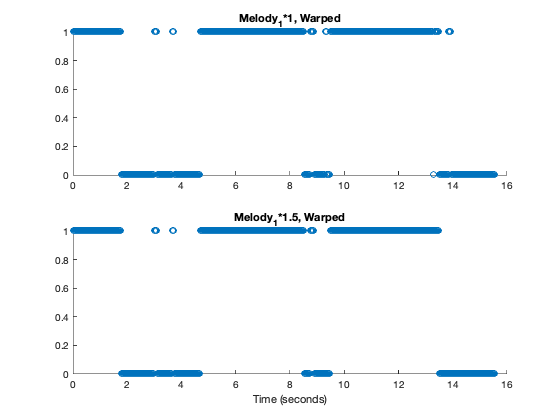


duration = t(end)
figure;
subplot(2,1,1)
scatter(t,a1w_org)
title('Melody_1*1, Warped')
subplot(2,1,2)
scatter(t,a1w_trans)

title('Melody_1*1.5, Warped')
xlabel('Time (seconds)')

Comparing original and transformed melody 2

a2w_org = features_song_2_org(i22);
a2w_trans = features_song_2(i12);

t = (0:lengthOfWindow:(numel(i12)-1)*lengthOfWindow);

duration = 9.8400

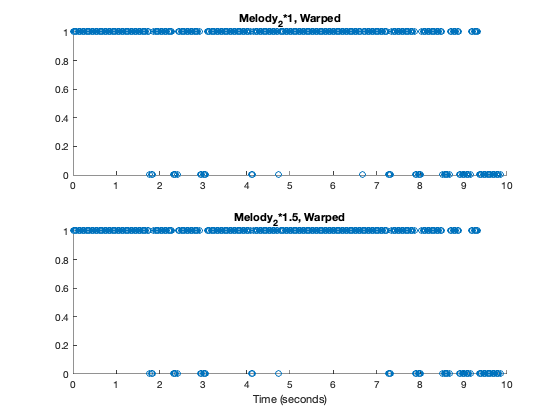


duration = t(end)
figure;
subplot(2,1,1)
scatter(t,a2w_org)
title('Melody_2*1, Warped')
subplot(2,1,2)
scatter(t,a2w_trans)

title('Melody_2*1.5, Warped')
xlabel('Time (seconds)')

Comparing original and transformed melody 3

a3w_org = features_song_3_org(i23);
a3w_trans = features_song_3(i13);

t = (0:lengthOfWindow:(numel(i13)-1)*lengthOfWindow);

duration = 8.3700

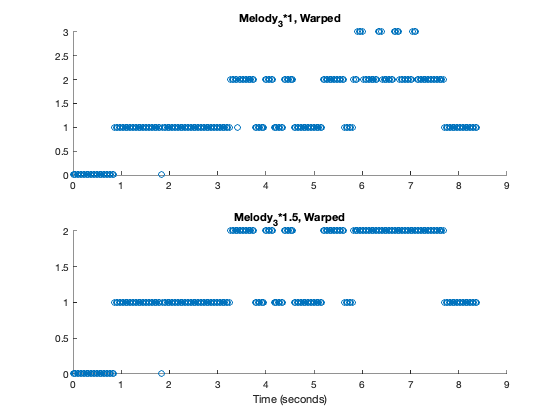


duration = t(end)
figure;
subplot(2,1,1)
scatter(t,a3w_org)
title('Melody_3*1, Warped')
subplot(2,1,2)
scatter(t,a3w_trans)

title('Melody_3*1.5, Warped')
xlabel('Time (seconds)')